3.

a) Probabilidade de colisão em hashing

N = 1e5;
T = 1000; 
k = 10; 

count  = 0;

array = randi(T,k,N);
for i = 1:N
    unique_array = unique(array(:,i));
    if length(unique_array) < 10
        count = count + 1;
    end
end

prob_colisao = count/N;
prob_colisao

prob_colisao = 0.0434

b)

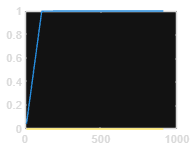

N = 1e5;
T = 1000; 
k = 10:100:1000;
 
probabilidades = zeros(length(k));

for i = 1:length(k)
    array = randi(T, k(i), N);
    count = 0;
    for j = 1:N
        unique_array = unique(array(:, j));
        if length(unique_array) < length(array(:, j))
            count = count + 1;
        end
    end
    prob_colisao = count / N;
    probabilidades(i) = prob_colisao;
end

plot(k, probabilidades);

c)

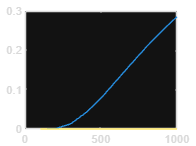

N = 1e5;
k = 50; 
T = 100:100:1000;
 
probabilidades = zeros(length(T));

for i = 1:length(T)
    array = randi(T(i), k, N);
    count = 0;
    for j = 1:N
        unique_array = unique(array(:, j));
        if length(unique_array) == length(array(:, j))
            count = count + 1;
        end
    end
    prob_colisao = count / N;
    probabilidades(i) = prob_colisao;
end

plot(T, probabilidades)